# The Fourier transform

"Any signal can be represented as a sum of sines and cosines of different frequencies."

One way to convince yourself of this fact is to think about linear algebra. If a signal is just a vector in N dimensions, say for N discrete samples of a signal in time, this Fourier decomposition can simply be thought of as a change in coordinates. Consider the set of vectors


$$
  \pmatrix{1  \cr 1  \cr \vdots \cr 1} 

\pmatrix{\cos(2\pi \times 1 \frac{0}{N}) \cr 
\cos(2\pi \times 1 \frac{1}{N}) \cr 
\vdots\cr 
\cos(2\pi \times 1 \frac{N-1}{N}}

\pmatrix{
\cos(2\pi \times 2 \frac{0}{N}) \cr
\cos(2\pi \times 2 \frac{1}{N}) \cr
\vdots\cr
\cos(2\pi \times 2 \frac{N-1}{N})}
\cdots,
\pmatrix{
\cos(2\pi \times N/2 \frac{0}{N}) \cr
\cos(2\pi \times N/2 \frac{1}{N}) \cr
\vdots\cr
\cos(2\pi \times N/2 \frac{N-1}{N})}
$$
$$
\pmatrix{
\sin(2\pi \times 1 \frac{0}{N}) \cr
\sin(2\pi \times 1 \frac{1}{N}) \cr
\vdots\cr
\sin(2\pi \times 1 \frac{N-1}{N})}


\pmatrix{
\sin(2\pi \times 2 \frac{0}{N}) \cr
\sin(2\pi \times 2 \frac{1}{N}) \cr
\vdots\cr
\sin(2\pi \times 2 \frac{N-1}{N})}
\cdots,
\pmatrix{
\sin(2\pi \times (N/2 - 1) \frac{0}{N}) \cr
\sin(2\pi \times (N/2 - 1) \frac{1}{N}) \cr
\vdots\cr
\sin(2\pi \times (N/2 - 1) \frac{N-1}{N})}

$$$$


(Generalized formula: $\cos \left(\frac{2\pi k}{N}n \right), \sin \left(\frac{2\pi k}{N}n \right)$, where $k$ represents the frequency.)

This might be a lot to process all at once, but it's just a discretized set of waves, where the independent variable defining the wave runs along the column axis. All frequencies up to N/2 are used, and by including both sine and cosine waves, we get to N total vectors. We call this set of vectors the "Fourier basis."

Just like how we can represent an N-dimensional signal as a sum of the N basis vectors [1,0,⋯,0],[0,1,⋯,0],⋯ etc., we can also represent it as a sum of these different N basis vectors defined above. All we need for that to be true is for the vectors to be *linearly independent*, which is a fancy way of saying "not redundant"---no vector in this finite set can be a combination of the others (if it were, it wouldn't offer anything new). In fact, not only is that true for the Fourier basis, something even stronger is: these vectors are mutually *orthogonal*!

% Exercise 1: Define the Fourier basis yourself
%  - Decide on a dimensionality of the signal N
% - Then define each vector and store them as rows of a matrix 
% - How do we want to order them? All the cosines then all the sines, or do
% we want cosines and sines of the same frequency to be next to each other?
% Doens't really matter as long as we know what it is for interpretation
% later. (Recommend pairing up cosines and sines though.)

% Note: ***You can assume N is even**! Odd case is slightly different and
% annoying so don't worry about it.

% your code here

N = 100;
Fourier_basis =get_Fourier_basis_solutions(N);

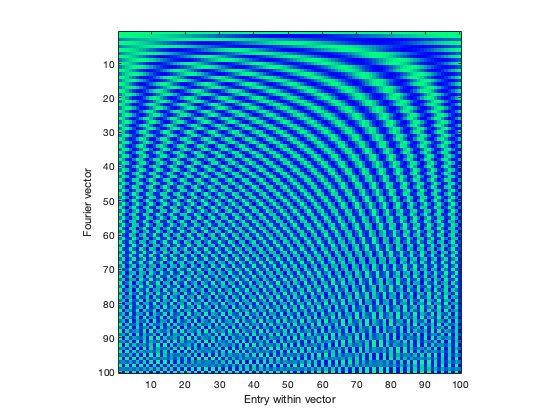

% Visualize this basis a matrix for fun
figure
imagesc(Fourier_basis); axis square
colormap winter
ylabel('Fourier vector')
xlabel('Entry within vector')

`Are these unit vectors? Take the norm of each row to investigate yourself`

Fourier_norms = sqrt(diag(Fourier_basis'*Fourier_basis))

Fourier_norms =     7.1414
    7.1414
    7.1414
    7.1414
    7.1414
    7.1414
    7.1414
    7.1414
    7.1414
    7.1414


% Exercise 2: Define a function that outputs the basis frequences for a
% given N The purpose is to have them available to plot on the x-axis. Make
% sure the result matches the way you defined Fourier_basis above! (You can
% assume N is even so we can stick to linear algebra and not have to dive
% into arithemtic :p) For example, if N = 10, we would have frequenices of
% [0, 1, 1, 2, 2, 3, 3, 4, 4, 5]

% code in the function file

Let's apply this to a signal:

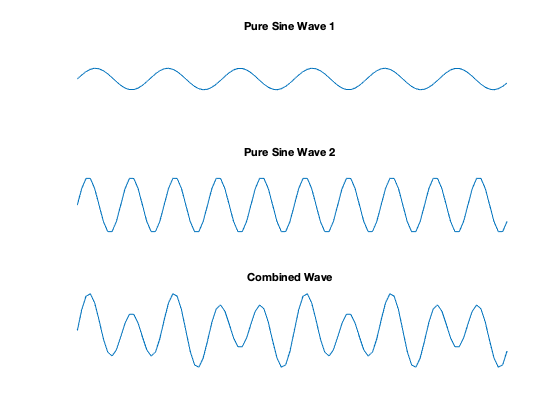

N      = 100;
n      = 0: N-1;
amp_1  = 0.5;
freq_1 = 6;
amp_2  = 1.3;
freq_2 = 10;
x      = amp_1 * sin(2 * pi * freq_1 * n / N) + amp_2 * sin(2 * pi * freq_2 * n / N);

%Let's plot each of these sinusoids individually as well as their sum

figure
subplot(3,1,1)
plot(amp_1 * sin(2 * pi * freq_1 * n / N))
ylim([-2, 2])
title('Pure Sine Wave 1')
axis off
subplot(3,1,2)
plot(amp_2 * sin(2 * pi * freq_2 * n / N))
ylim([-2, 2])
title('Pure Sine Wave 2')
axis off
subplot(3,1,3)
plot(x)
ylim([-2, 2])
title('Combined Wave')
axis off

Transform the signal x using the Fourier basis you computed (think projection!) and plot with frequencies on the x-axis according to your function above

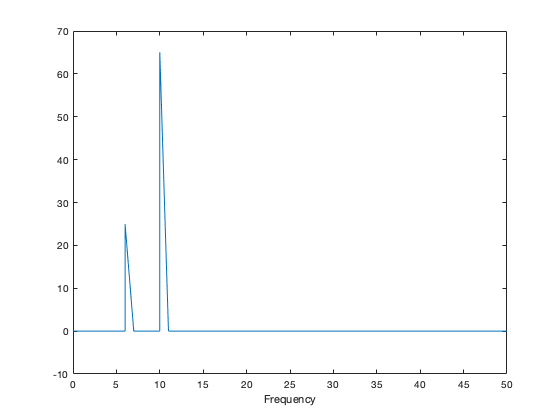


%your code here

figure
F_x = Fourier_basis*x';
plot(get_frequencies_solutions(N), F_x)
xlabel('Frequency')

Note that since we doubled-up sines and cosines, every frequency on the x-axis is paired with an identical frequency for the other sine/cosine. Let's illustrate with a different signal:

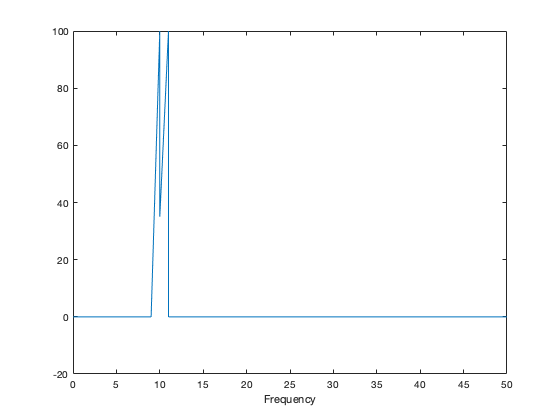


N = 100;
n = 0: N-1;
% Different set of amplitudes and frequencies
amp_1  = 2;
freq_1 = 10;
amp_2  = 0.7;
freq_2 = 10;
amp_3  = 2;
freq_3 = 11;
x = (amp_1 * cos(2 * pi * freq_1 * n / N) + amp_2 * sin(2 * pi * freq_2 * n / N) + amp_3 * cos(2 * pi * freq_3 * n/ N));


%your code here
figure
F_x = Fourier_basis*x';
plot(get_frequencies_solutions(N), F_x)
xlabel('Frequency')

Although the locations of the spikes make sense--at frequencies corresponding to the waves we entered--it's hard to interpret their magnitudes. The Fourier basis vectors we computed weren't unit vectors, after all.

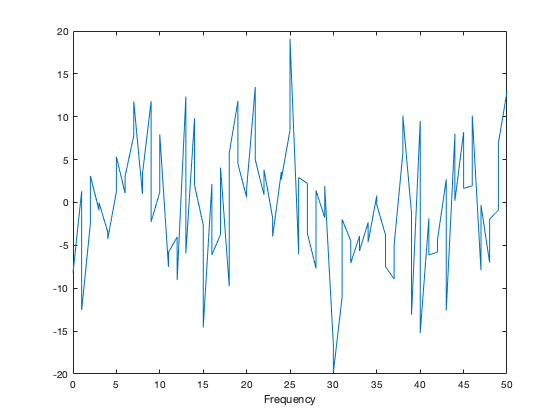

%Let's try signals that are not sparse combinations of sines and cosines
N = 100;
x = randn(1,N);
Fourier_basis = get_Fourier_basis_solutions(N);

% your code here
figure
F_x = Fourier_basis*x';
plot(get_frequencies_solutions(N), F_x)
xlabel('Frequency')

% Exercise 3: Define your own signals as mixes of sines and cosines--or as
% anything you want! Transform them under the Fourier basis

% your code here

## White noise

What if we put in a signal with absolutely no structure to it? That is, each element x[n] is an identically, independently sampled number from a Gaussian distribution N(0,1), as we did above. What should we expect for the Fourier transform?

From the example above with Gaussian noise, this looks "flat" but it's hard to tell, especially with the sines and cosines of the same frequency "scrunched up" next to each other. What'd be nice is if we could get a cleaner graph telling us how much general sine and cosine action we have going on at each frequency.

## Signal Power

At a given frequency, the signal can be decomposed into its cosine and sine component at that frequency. These are really only different by a π/2 phase shift. What if we want to know the overall "power" at that frequency? We don't care whether it's positive or negative, and we don't care whether it's contained in the sines or cosines, we just want to know how much action is happening at each frequency. This is important for say analyzing the spectral content of sunlight--we don't care the phase of the UV radiation, we just want to know how much UV radiation is in there. To do this, we can simply compute:


$$
$$P(f) = (\vec{x} \cdot \cos(2\pi f \vec{n} / N))^2 + (\vec{x} \cdot \sin(2\pi f \vec{n} / N))^2$$
$$


But we already have these projection values from the Fourier transformation, so we just need to select, square, and add up the right pairs. The function `get_signal_power` does just that.

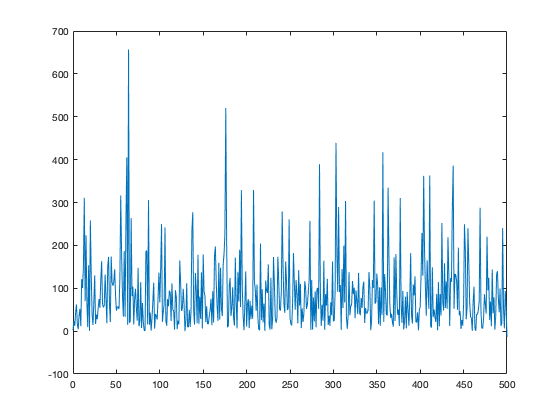

% Plot the power of a white noise signal
N = 1000;
sigma = 0.3;
x = sigma.*randn(1, N); % white noise
Fourier_basis = get_Fourier_basis_solutions(N);

figure
F_x = Fourier_basis*x';
F_x_power = get_signal_power(F_x);
frequencies = 0:N/2;
plot(frequencies, F_x_power)

Try this for different values of sigma, and rerun it repeatedly to get new random outcomes. What if we averaged the result over many trials of this--what would the shape of the spectrum be?

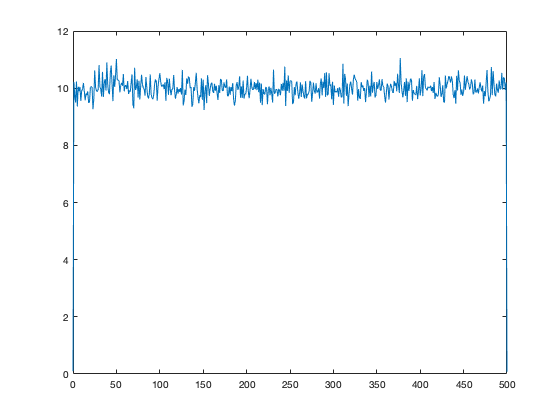

N_avg = 1000;
N = 1000;
sigma = 0.1;
Fourier_basis = get_Fourier_basis_solutions(N);
power_spectra = nan(N_avg,N/2+1);

figure()
for ii = 1:N_avg
    x = sigma.*randn(1, N); %latest white noise sample
    F_x = Fourier_basis*x';
    F_x_power = get_signal_power(F_x);
    
    
    power_spectra(ii,:) = F_x_power;
end

frequencies = 0:N/2;
plot(frequencies, mean(power_spectra))

# The Fast Fourier Transform

We've got a roller coaster of bad news and good news.

Bad news:

-The way we're doing the Fourier transform doesn't scale efficiently, as we have to multiply N2 numbers to do this matrix-vector product, and that's assuming the Fourier basis for our signal is already generated and ready to go. For signals with high sampling rates, N can be quite huge.

Good news:

-There is a method, called the *Fast Fourier Transform* that manages to do this same computation in NlogN time! For big N, this is an *enormous* speed-up.

Back to bad news:

-To compute via FFT in MATLAB, we have to use a black-box method and understand its slightly counterintuitive way of reporting the output. And this involves complex numbers. This may sound scary, but it's just ways of organizing sine and cosine waves.

% Try out the fft function on a signal and see what you get

N = 100;
n = 0: N-1;
x = 0.5 * sin(2 * pi * 6 * n / N) + 1.3 * sin(2 * pi * 10 * n / N);

F_x = fft(x);
%print a few values of this output, what's it look like?
F_x(1:10)

ans =    0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 -25.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


Oof, looks like we have some complex numbers in here. That's annoying, cause we only fed in real numbers!

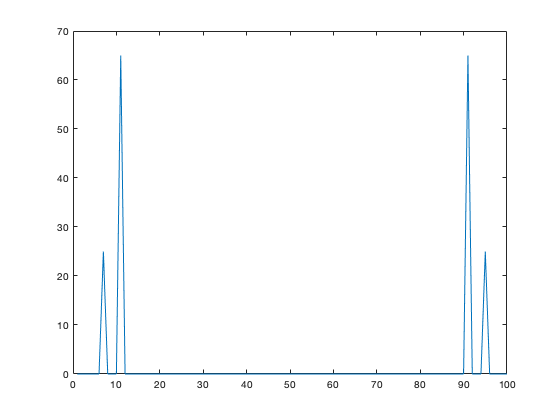

% Try plotting the absolute values of these complex numbers
figure
plot(abs(F_x))

## How the FFT works

The FFT assumes you have a *complex* signal in N dimensions. This is more (precisely twice as much more) information as in a real signal. And the output matches this increased information: the output of the FFT is an N-dimensional vector with complex entries. Specifically, the FFT finds the projections of the signal onto this set of N basis vectors:


$$
\pmatrix{
e^{2\pi i k \frac{0}{N}}\cr
e^{2\pi i k \frac{1}{N}}\cr
\vdots \cr
e^{2\pi i k \frac{N-1}{N}}
} \text{ for } k = 0, \cdots, N - 1$$


Why these? Short answer: mathematical elegance. We lose the immediate interpretability of pure cosines and sines as common sense "waves," but we gain the ease of algebra that comes with complex exponentials. We'll see the payoff of this soon. But for now, how do we interpret this if we just want to keep things real?

If you start with a real signal to begin with, the output is guaranteed to have certain symmetry properties. Thus you can discard part of the output that doesn't tell you anything new. In particular, the second half of the result doesn't tell us anything the first half doesn't. If $$\vec{x} \in \mathbb{R}^N$$is an N-dimensional vector with real entries, then


$$$$\vec{f} = \text{fft}(\vec{x}) \in \mathbb{C}^N$$$$


`has symmetries`


$$
$$\text{real}(f_k) = \text{real}(f_{N-k})$$$$


and


$$$$\text{imag}(f_k) = -\text{imag}(f_{N-k})$$$$


In words, if we flip the output along the middle of the x-axis (i.e. move k to N−k), we get either the same real part or the negated imaginary part--in both cases, we *learn no new information*. So we can simply discard the second half of the signal. **Then the real part of the first half maps onto the cosines for our original Fourier transform, and the negative imaginary part maps onto the sines**. By extracing the real and imaginary parts (themselves both real!) of these signals, we get back to a fully real N-dimensional signal, as before.

We'll get a feel for this on some examples below.

% Exercise 4: Using complex numbers in  z = x + y * 1i, 
% define the Fourier basis as written above in the manner
% we defined Fourier_basis before, as a matrix whose rows
% are each individual basis vector.

%your code here
N = 100;
n = 0: N-1;
F = nan(100);
for k= n
    F(k+1,:)=(exp(-2 * pi * k * n * (1j) / N));
end


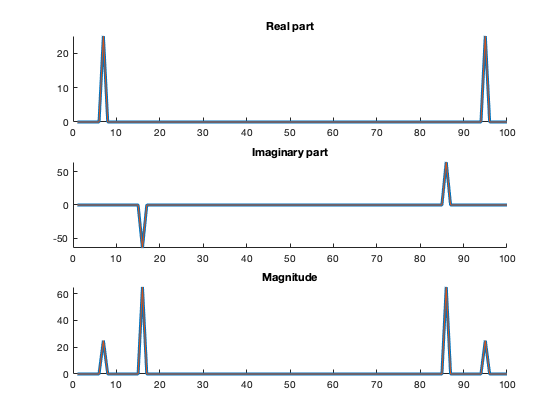

% Exercise 5: Define a signal and take its projection onto this new Fourier
% basis. Verify that the output is the same as that of the built-in fft
% function.(Use "linewidth" argument in plotting function to see that they
% plot right on top of each other)

N      = 100;
n      = 0: N-1;
amp_1  = 0.5;
freq_1 = 6;
amp_2  = 1.3;
freq_2 = 15;
x      = amp_1 * cos(2 * pi * freq_1 * n / N) + amp_2 * sin(2 * pi * freq_2 * n / N);

% your code here
F_x_1 = fft(x); %Fourier transform via fft function
F_x_2 = F*x'; %Fourier transform "by hand"
figure
subplot(3,1,1)
hold on
plot(real(F_x_1), 'linewidth',3)
plot(real(F_x_2))
title('Real part')

subplot(3,1,2)
hold on
plot(imag(F_x_1), 'linewidth',3)
plot(imag(F_x_2))
title('Imaginary part')

subplot(3,1,3)
hold on
plot(abs(F_x_1), 'linewidth',3)
plot(abs(F_x_2))
title('Magnitude')

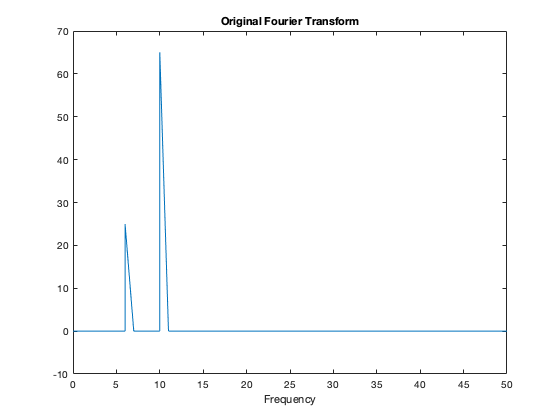

% Exercise 6: Now plot this same signal under our original Fourier basis.
% Can you figure out how the result of this computation maps onto the
% complex case? Explicitly extract the relevant quantities from the fft()
% result and show that they are ultimately the same as the original Fourier
% transformation when rearranged properly.

%Define example signal with pure sine waves

N      = 100;
n      = 0: N-1; %All time points in an array
amp_1  = 0.5;
freq_1 = 6;
amp_2  = 1.3;
freq_2 = 10;
x      = amp_1 * sin(2 * pi * freq_1 * n / N) + amp_2 * sin(2 * pi * freq_2 * n / N);

% Get our original Fourier transform via our Fourier basis
FB           = get_Fourier_basis_solutions(N);
original_F_x = FB*x';
% Get the Fourier transform as computed via FFT
fft_F_x      = fft(x);

%Plot original
figure
plot(get_frequencies_solutions(N), original_F_x)
title('Original Fourier Transform')
xlabel('Frequency')

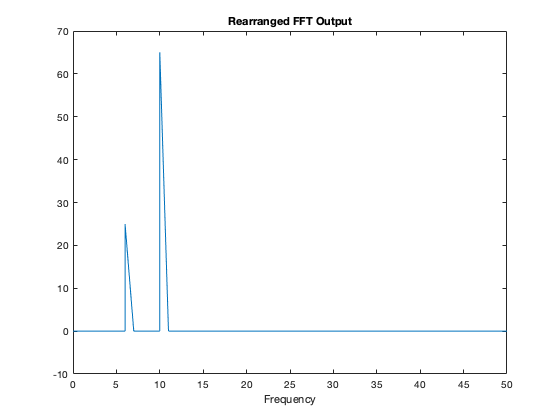


% Plot fft rearranged

% your code here

% Extract only the first half of the signal
half_signal = fft_F_x(1:N/2+1);

% Get the cosine and sine weights as real and negative imaginary parts
cosines = real(half_signal);
sines = -imag(half_signal);

% Remove the first and last real signals and concatenate the cosines and
% sines. Then re-order the array so that cosines and sines of same
% frequency are next to each other [cos1, cos2, cos3, sin1, sin2, sin3] ->
% [cos1, sin1, cos2, sin2, cos3, sin3]

cosines_and_sines = [cosines(2:end-1); sines(2:end-1)];
neighboring_freq = cosines_and_sines(:);

%Add the first and last cosine and sine back in
fft_remapped = [cosines(1), neighboring_freq', cosines(end)];

figure
plot(get_frequencies_solutions(N), fft_remapped)
title('Rearranged FFT Output')
xlabel('Frequency')

# **The Convolution Theorem (or Why Complex Numbers?)**

Well that was a bit of a pain, all that reshaping and extracting real numbers from the complex output just to match our first intuitive sense of what a Fourier transform. Why did we do it?

The reason, simply, is that math with complex numbers gets really nice. Let's say you have a voltage $v[t] = \cos(\omega t)$ and you want to apply some linear, shift-invariant system to it $Lv[t]$. We learned from class that, due to the linearity and shift-invariance of the system $L$, the only possible change that can be made to $$v[t]$$ is an *amplitude change* $A(\omega)$ and a *phase shift* $\phi(\omega)$:


$$Lv[t] = A(\omega) \cos(\omega t - \phi(\omega))$$


This is pretty simple, but we can get even simpler. Instead of thinking of the phase shift as this awkward "go inside the function argument and subtract by something" operation we currently have going, **what if both the amplitude change and phase shift could be interpreted as a single multiplication?**

To accomplish this, let's interpret $v[t]$ as the real part of a complex signal $z[t] = v[t] + y[t]i$. Complex signals mostly don't exist in nature, but they do exist in our minds. If we define $y[t] = \sin(\omega t)$, we can use the definition of a complex exponential to write


$$z[t] = \cos(\omega t) + i \sin(\omega t) = e^{i \omega t}$$


Then imagine if we define action on $z[t]$ via $L$ as multiplying by the complex number $A(\omega)e^{-i\phi(\omega)}$. What happens?


$$Lz[t] = A(\omega)e^{-i\phi(\omega)} e^{i \omega t} = A(\omega)e^{i(\omega t- \phi(\omega))} = A(\omega)\left[ \cos(\omega t - \phi(\omega)) + i \sin(\omega t - \phi(\omega))\right]$$


If we take the real part at the end, we get back our amplitude-scaled, phase-shifted signal from before!


$$\text{real}(Lz[t]) = A(\omega) \cos(\omega t - \phi(\omega)) = Lv[t]$$


# Connection with eigenvectors/eigenvalues

So you mean to tell me, we could operate with $L$ on our vector $e^{i\omega t}$... OR we could multiply it by $A(\omega)e^{-i\phi(\omega) t}$... and we get the same thing?!

### This is the definition of an eigenvector/eigenvalue

In normal matrix math, we say $\lambda$ is an eigenvalue of $A$ with corresponding eigenvector $\vec{v}$ if $A\vec{v} = \lambda \vec{v}$. Here we're saying, if $\vec{v} = e^{i\omega t}$, then


$$L\vec{v} = A(\omega)e^{-i\phi(\omega)} \vec{v}$$


so $\vec{v} = e^{i\omega t}$ is the eigenvector, while $\lambda = A(\omega)e^{-i\phi(\omega)}$ is the eigenvalue.

Exercise 7: Recall that a linear, shift-invariant system can be characterized by convolution with some kernel R. And further, that this convolution can be translated (if inefficiently) into matrix multiplication by repeating shifted versions of R along the columns. Perform eigenvalue analysis on such a matrix--what do the eigenvectors look like? Do they remind you of anything?

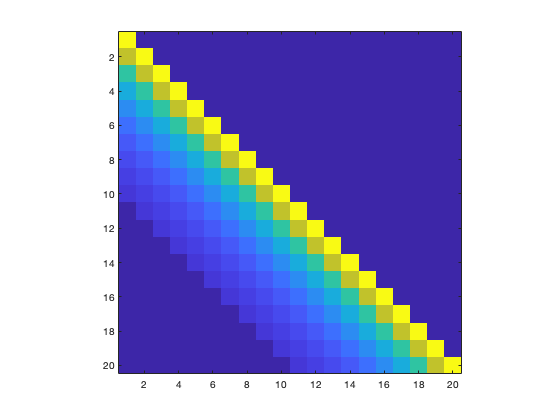

N = 100;
kernel = zeros(1,N);
t = 0:9;
kernel(1:10) = exp(-0.3.* t); %Define exponentially decaying kernel

%Generate convolution matrix R
R = zeros(N, N);
for i = 1:N
    R(:, i) = circshift(kernel, i-1);
end

%Visualize this convolution matrix on a small patch of it
figure
imagesc(R(1:20, 1:20)); axis square;
colormap parula

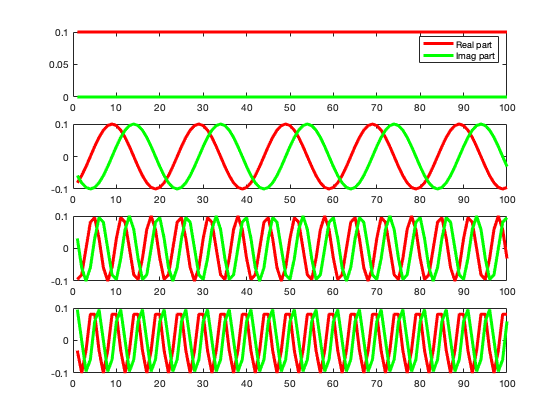

%Now take the eigendecomposition of R and analyze the eigenvectors. 
%Are they complex? Plot their real and imaginary parts for some of them

%your code here
[vecs, eigs] = eig(R);

vecs_to_plot = [1, 11, 31, 41];
figure
for i = 1:length(vecs_to_plot)
    subplot(length(vecs_to_plot),1,i)
    plot(real(vecs(:,vecs_to_plot(i))),'r','LineWidth',3); hold on
    plot(imag(vecs(:,vecs_to_plot(i))),'g','LineWidth',3); hold off
    if i == 1; legend({'Real part','Imag part'}); end
end

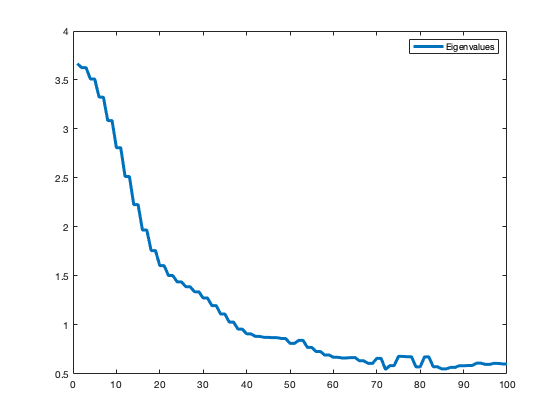

%Execise 7 continued: How do we interpret the eigenvalues? 
%Plot the absolute values of the eigenvalues
figure
plot(abs(diag(eigs)),'LineWidth',3); legend('Eigenvalues');

# Making the connection between convolution and eigenvalues: filters

Let's define a "Gaussian average" filter of size 5. What effect, intuitively, should this have on a signal? (It's basically a running average, right?)

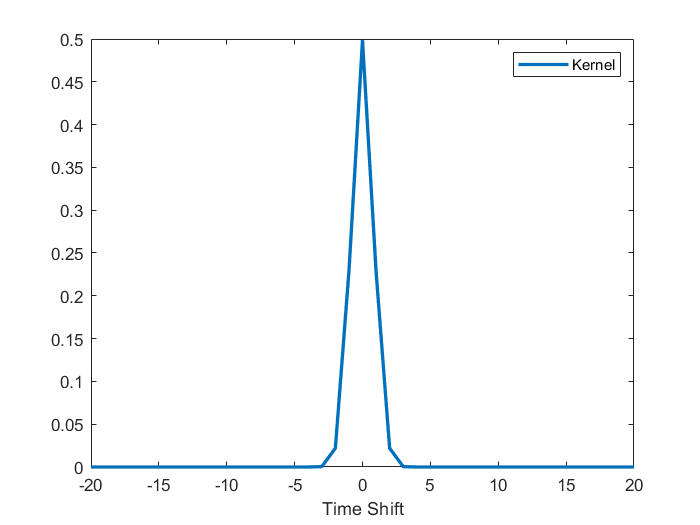

t_range = 20;
sigma   = 0.8;
kernel = get_gaussian_kernel(sigma, t_range);

figure
plot(-t_range:t_range, kernel,'LineWidth',2);
xlabel('Time Shift'); legend('Kernel')

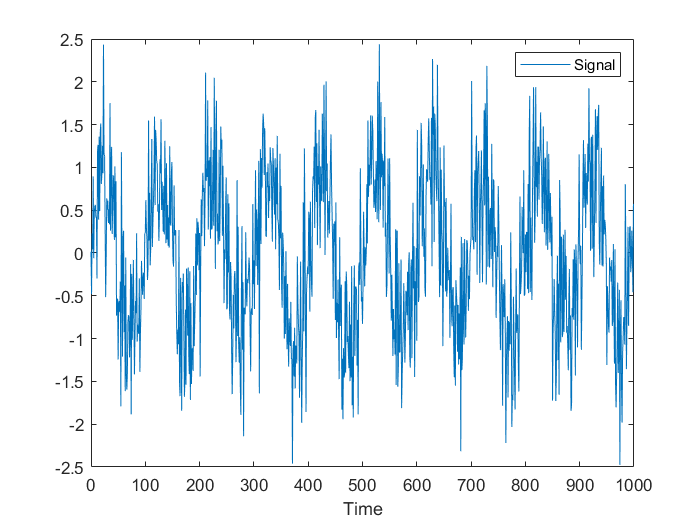

%Define a signal that has a clear separation of "signal" and noise
N = 1000;
t = 0:N-1;
f = 10;
noise_scale = 0.6;
x = sin(2.*pi.*f.*t./N) + noise_scale.* randn(1,N);

figure
plot(t,x); xlabel('Time'); legend('Signal')

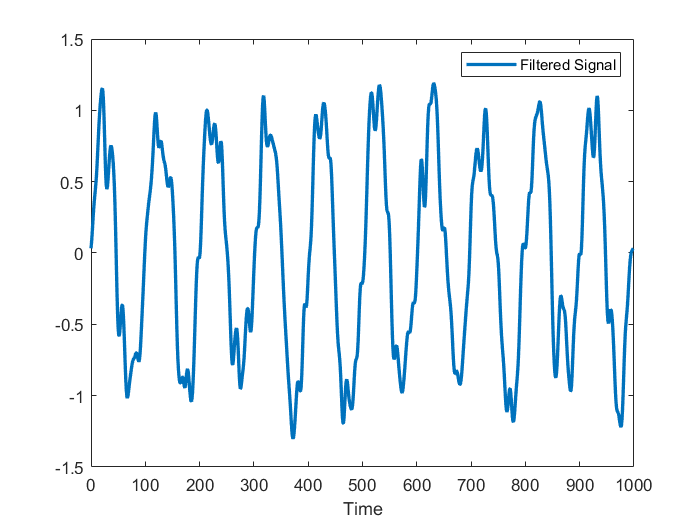

%Exericse 8: Convolve this signal with our kernel function, using "same"
%and plot the result. Change the values of sigma and t_range and see what
%the effect is

%your code here
kernel = get_gaussian_kernel(3, 20);
y = conv(x, kernel,'same'); 

figure
plot(t,y,'lineWidth',2); xlabel('Time'); legend('Filtered Signal')

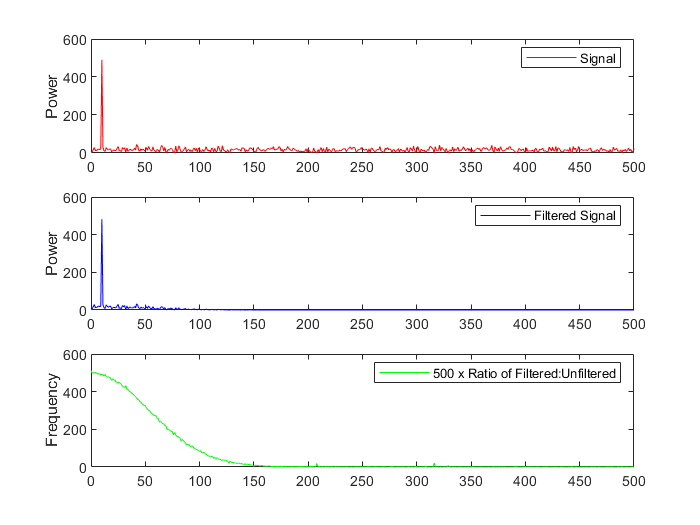

%Exercise 9: Finally, plot the power spectrum of the original signal x,
%the spectrum of the convolved signal with the kernel. Plot their ratio
%at each frequency. What relationship do you see?

%your code here
F_x = fft(x);
F_x_power = abs(F_x(1:floor(N/2)+1));


F_y = fft(y);
F_y_power = abs(F_y(1:floor(N/2)+1));

figure
subplot(3,1,1)
frequencies = 0:floor(N/2);
plot(frequencies, F_x_power, 'Color', 'r'); ylabel('Power'); legend('Signal');

subplot(3,1,2)
plot(frequencies, F_y_power, 'Color', 'b');ylabel('Power'); legend('Filtered Signal');

subplot(3,1,3)
plot(frequencies, 500.* F_y_power./ F_x_power, 'Color', 'g');ylabel('Frequency'); 
legend('500 x Ratio of Filtered:Unfiltered');

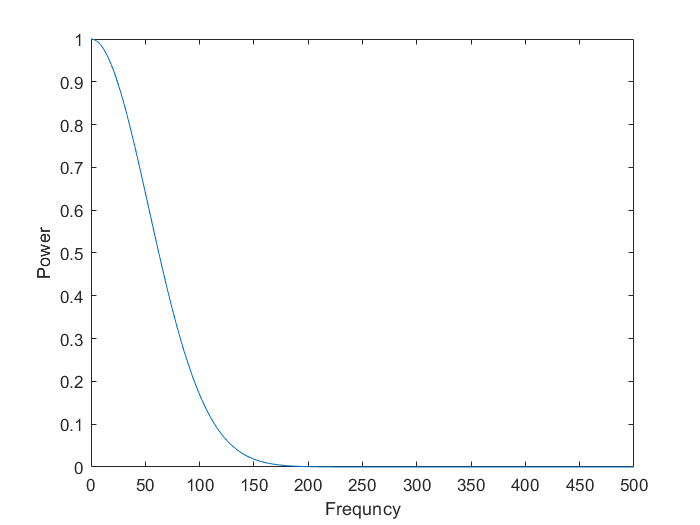

%Exercise 10: Compute the power of the *kernel itself* you used above. 
%Hint: you may need to zero pad to make it the same dimensions as the
%original signal.

padded_kernel = horzcat(kernel, zeros(1, N - length(kernel)));

%your code here
F_r = fft(padded_kernel);
F_r_power = abs(F_r(1:floor(length(F_r)/2)+1));
frequencies = 0:floor(length(F_r)/2);

figure
plot(frequencies, F_r_power);
xlabel('Frequncy'); ylabel('Power')

%Exercise 11: Can we recover this from the spectrum of the convolution matrix?
% - Compute the convolution matrix by "rolling" the padded kernel as before
% - Compute its eigenvalues.
% - Plot their norms. Recognize this?

%your code here
R = zeros(N, N);
for i = 1:N
    R(:, i) = circshift(padded_kernel, i);
end
[vecs, eigs] = eig(R);

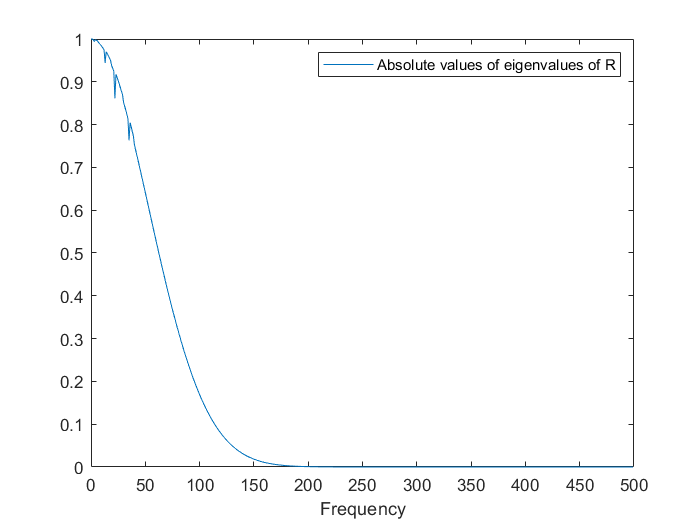

eigV = abs(diag(eigs));
figure
plot(frequencies(1:end-1), eigV(1:2:end)');
xlabel('Frequency')
legend('Absolute values of eigenvalues of R')